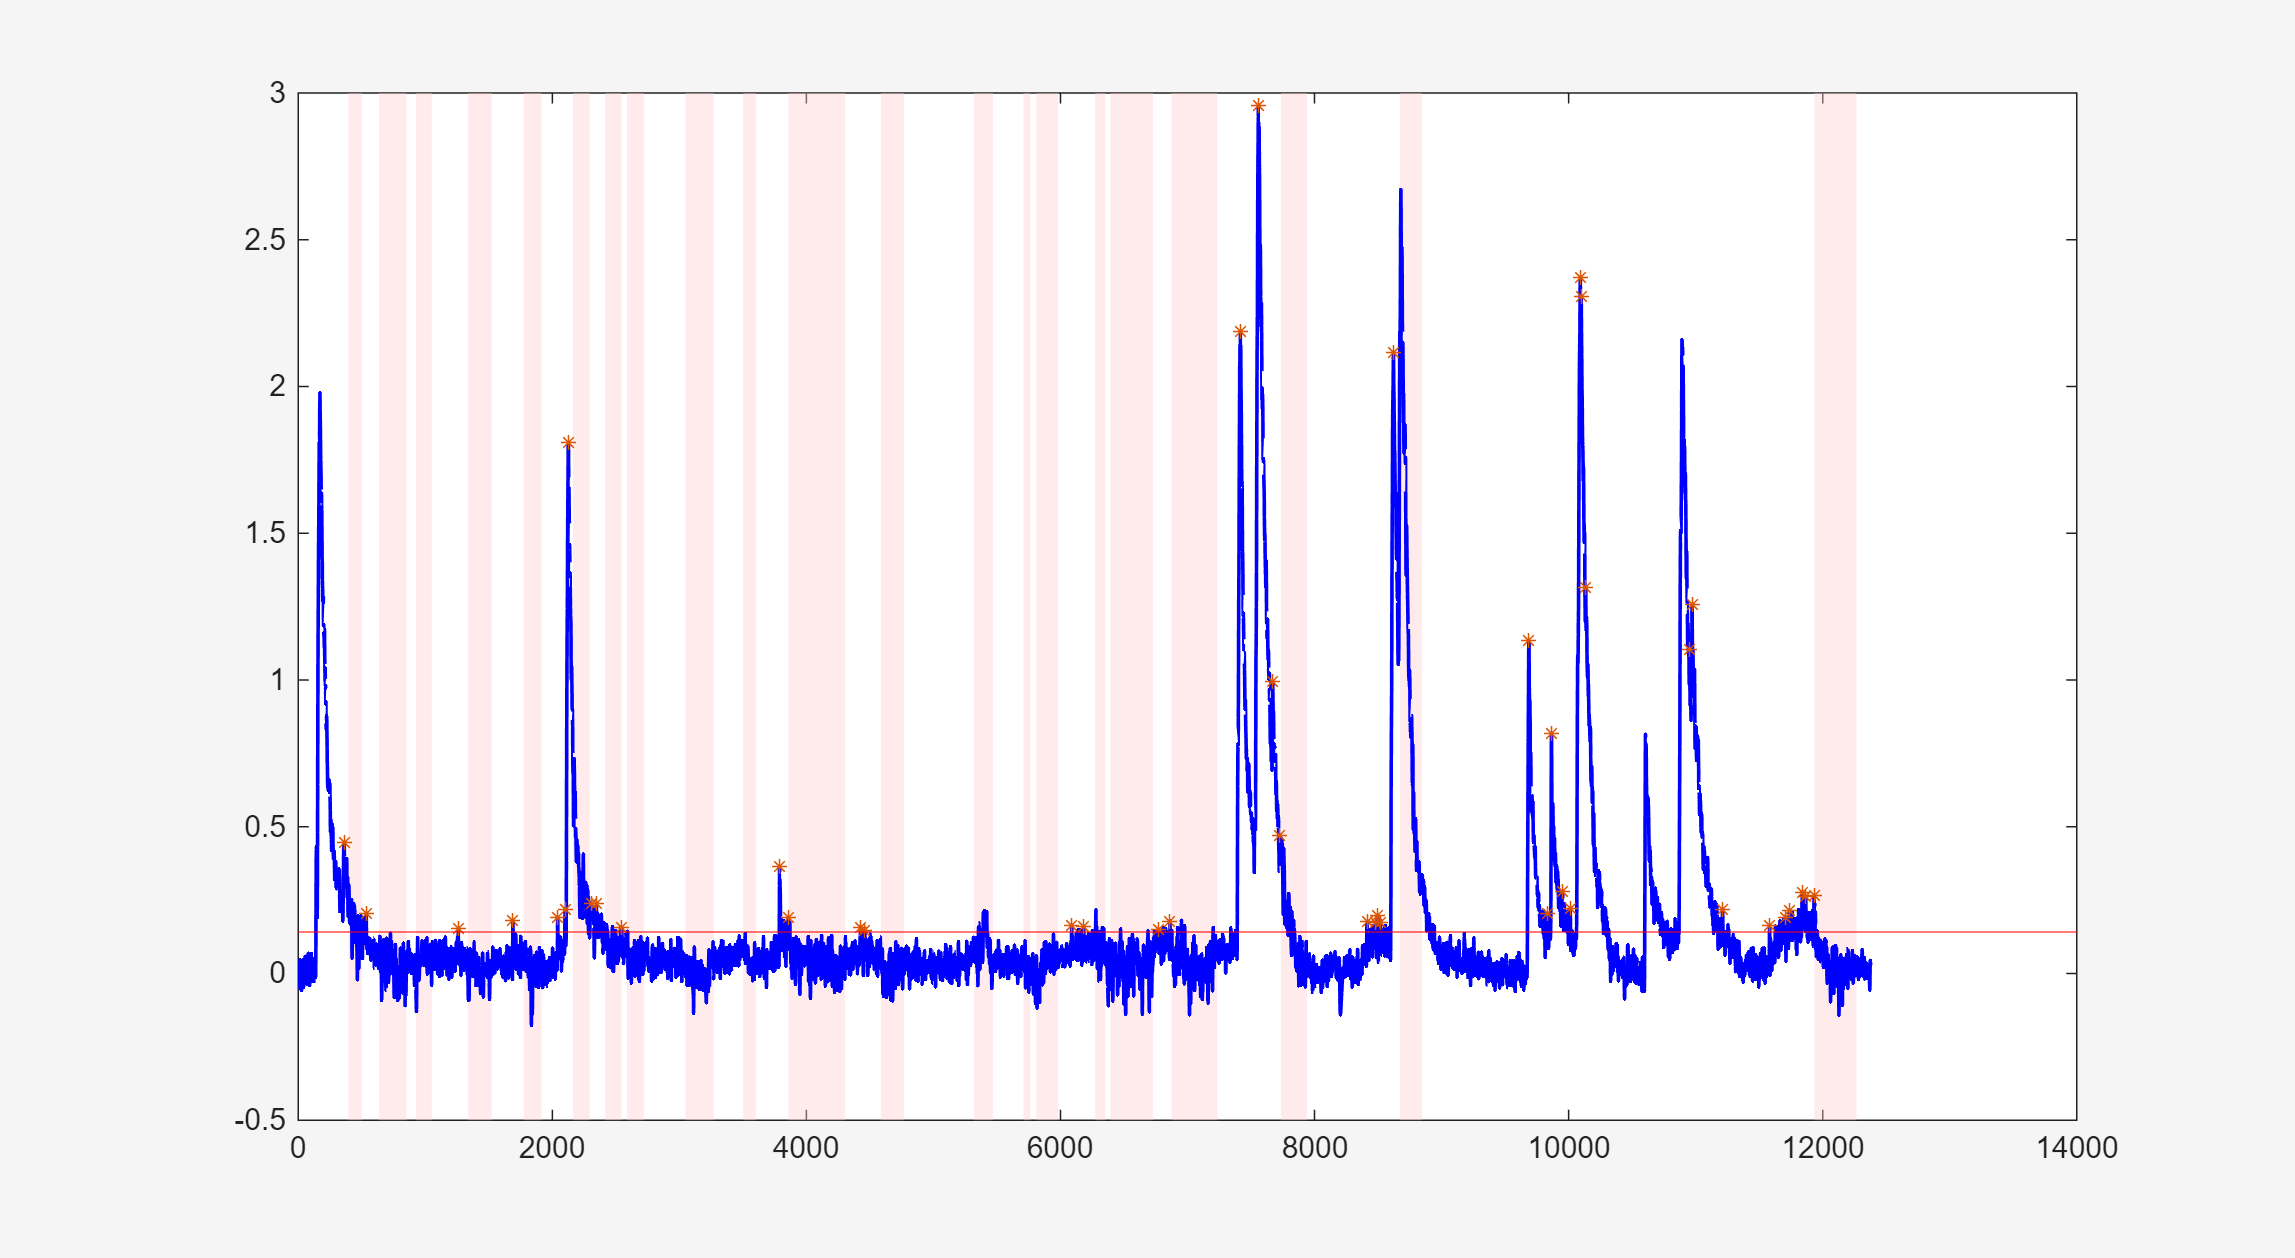

cell_idx = 2;
locs = find(Raster(cell_idx, :) == 1);

figure(Visible='on');

plot(Tr1b(cell_idx, :), 'b-', 'LineWidth', 1.2);
hold on;
% fenetre=zeros(1,Nz);
% fenetre(WinActive)=1;
% plot (fenetre)

% plot(Fdetrend(1, :), 'b-', 'LineWidth', 1.2,'Color','green');
% 3. Superposer les pics en utilisant les indices extraits du Raster (en rouge)
plot(locs, Tr1b(cell_idx, locs), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
yline(th_detection(cell_idx),'Color','red')
% title (['num' , num2str(cell_idx)])
% yyaxis right
% % plot (speed)
% fenetre=zeros(1,Nz);
% fenetre(WinRest)=1;
% plot (fenetre)
 %color coding rest period
    y_lims = ylim;
    y_min = y_lims(1);
    y_max = y_lims(2);
    is_active=ones(1,Nz);
    is_active(WinRest)=0;
    transitions = diff([0, is_active, 0]);
    debuts = find(transitions == 1);
    fins = find(transitions == -1) - 1;
    X_rect = [debuts; debuts; fins; fins];
    Y_rect = repmat([y_min; y_max; y_max; y_min], 1, length(debuts));
    hold on;
    p = patch(X_rect, Y_rect, [1, 0.8, 0.8], 'EdgeColor', 'none');
    p.FaceAlpha = 0.4;
    uistack(p, 'bottom');

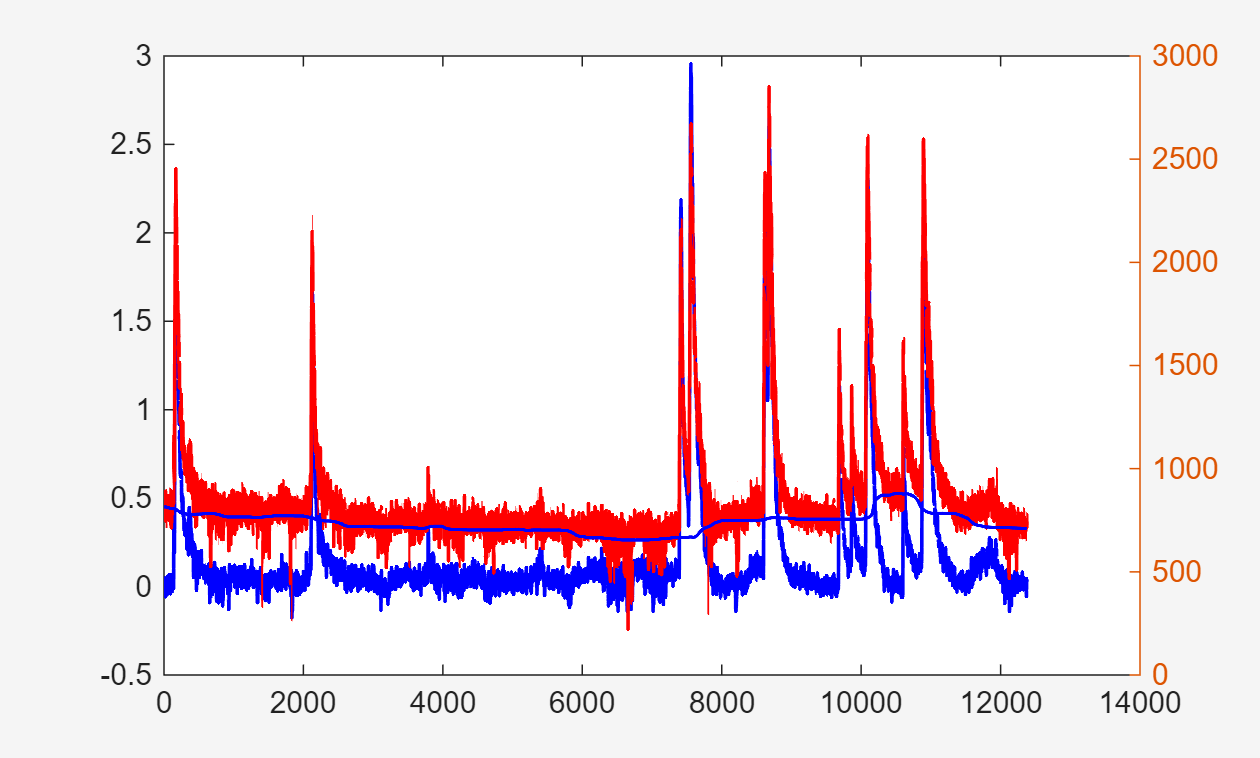


    % --- PATCH 2 : Color coding des BURSTS (Nouvel ajout en jaune clair) ---
transitions_burst = diff([0, burst_trace, 0]);
debuts_b = find(transitions_burst == 1);
fins_b = find(transitions_burst == -1) - 1;
if ~isempty(debuts_b)
    X_rect_b = [debuts_b; debuts_b; fins_b; fins_b];
    Y_rect_b = repmat([y_min; y_max; y_max; y_min], 1, length(debuts_b));
    % Couleur RGB [0.95, 0.9, 0.6] correspond à un jaune/beige léger
    p_burst = patch(X_rect_b, Y_rect_b, [0.95, 0.9, 0.6], 'EdgeColor', 'none');
    p_burst.FaceAlpha = 0.5;
    uistack(p_burst, 'bottom'); % Le met au fond pour ne pas cacher le signal
end

    % exportgraphics(gcf,strcat(namefull, 'trace_cell_', num2str(i), '.png'),'Resolution',300)
    % close gcf

figure(Visible="on")
plot(Tr1b(cell_idx, :), 'b-', 'LineWidth', 1.2);
hold on

yyaxis right
plot(F(cell_idx, :), 'r-', 'LineWidth', 1.2);
plot(Fzero(cell_idx, :), 'b-', 'LineWidth', 1.2);
hold off



%%mad valeur négative
for i = 1%:NCell
    % trace_lissee = Tr1b(i, :); % Votre trace actuelle, déjà passée par SG
    % 
    % % 1. Trouver la ligne de base glissante (pour centrer le bruit sur 0)
    % % movmedian ignore les grands pics et trace une ligne au milieu du bruit résiduel
    % baseline = movmedian(trace_lissee, 200); 
    % trace_centree = trace_lissee - baseline;
    trace_centree = Tr1b(i, :);
    % 2. MESURER LE BRUIT RÉSIDUEL (L'astuce de la moitié négative)
    % On isole uniquement les valeurs qui sont en-dessous de 0.
    % C'est le reflet parfait de vos ondulations résiduelles sans AUCUN pic.
    valeurs_negatives = trace_centree(trace_centree < 0);
    
    % On calcule le MAD par rapport à 0 sur cette moitié, 
    % et on multiplie par 1.4826 pour avoir l'équivalent d'un écart-type (sigma).
    sigma_residuel = 1.4826 * median(abs(valeurs_negatives));
    
    % Sécurité basique
    if sigma_residuel < 0.05
        sigma_residuel = 0.05;
    end
    
    % 3. Définir le seuil directement lié à ce que vous voyez
    seuil_detection = 3.5 * sigma_residuel;
    
    % % 4. Détecter les pics (on travaille sur trace_centree pour que le seuil soit fixe)
    % [amplitude, locs] = findpeaks(trace_centree, ...
    %     'MinPeakHeight', seuil_detection, ...
    %     'MinPeakProminence', seuil_detection, ...
    %     'MinPeakDistance', MinPeakDistance);
    % 
    % % ... suite du code
end

  %  95%=1.64 99%=2.33 99.9=3.09
% noise=  1.4826 * mad(diff(F(1, :)))/ sqrt(2)
% seuil= 3.09 * noise 

MinPeakDistance    = 3;
fenetre_correction = 400; 

%cellules_choisies = randperm(NCell, 10);
cellules_choisies=[20,21,37,53,66];
for i=1:NCell%cellules_choisies
    noise(i)= 1.4826 * mad(diff(DFF0(i, :)))/ sqrt(2);
end
figure
plot(noise)


for i=[250,436,311,24]%cellules_choisies
    noise= 1.4826 * mad(diff(DFF0(i, :)))/ sqrt(2);
    % seuil_detection= 3.09 * noise ;
    seuil_detection= 2.33 * noise ;
    baseline_locale = movmedian(Tr1b(i, :), fenetre_correction);
    Tr1b_plate = Tr1b(i, :) - baseline_locale;

    % [amplitude, locs] = findpeaks(Tr1b_plate,
    [amplitude, locs] = findpeaks(Tr1b_plate, ...
    'MinPeakHeight', seuil_detection, ...
    'MinPeakProminence', seuil_detection*0.8, ...
    'MinPeakDistance', MinPeakDistance);
    
    % noise= 1.4826 * mad(diff(Tr1b(1, :)))/ sqrt(2)
    % seuil= 3.09 * noise 
    
    figure(Visible='on');
    % 2. Tracer la trace originale de la cellule (en bleu)
    % plot(Tr1b(i, :), 'b-', 'LineWidth', 1.2);
    plot(Tr1b_plate, 'b-', 'LineWidth', 1.2);
    hold on;
    % plot(Fdetrend(1, :), 'b-', 'LineWidth', 1.2,'Color','green');
    % 3. Superposer les pics en utilisant les indices extraits du Raster (en rouge)
    plot(locs, Tr1b(i, locs), '*', 'MarkerSize', 5, 'MarkerFaceColor', 'r');
    yline(seuil_detection,'Color','red')
    title (['num' , num2str(i)])

    % figure(Visible='on');
    % % 2. Tracer la trace originale de la cellule (en bleu)
    % plot(Tr1b(i, :)-noise, 'b-', 'LineWidth', 1.2);
    % hold on;
    % % plot(Fdetrend(1, :), 'b-', 'LineWidth', 1.2,'Color','green');
    % % 3. Superposer les pics en utilisant les indices extraits du Raster (en rouge)
    % plot(locs, Tr1b_plate(locs)-noise, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    % yline(seuil_detection,'Color','red')
    % title (['num' , num2str(i), ' plate'])
end

cell_idx=1;
indices_pics_raster = find(Raster(cell_idx, :) == 1);

figure;
% 2. Tracer la trace originale de la cellule (en bleu)
plot(Tr1b(cell_idx, :), 'b-', 'LineWidth', 1.2);
hold on;

% 3. Superposer les pics en utilisant les indices extraits du Raster (en rouge)
plot(indices_pics_raster, Tr1b(cell_idx, indices_pics_raster), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

yline(th(cell_idx))
yline(seuil_detection,'Color','red')

%plot(WinActive_bin)

hold off;